# Teoria S9

format long g

f=@(x)log(x);
k=0:14;
h=1./10.^k;
for n=1:15
    fp(n)= (f(2+h(n))-f(2))/h(n);
end

er= abs(fp-0.5); %0.5 valor derivada  de ln(x) en x=2
res=[k;h;fp;er]'

res =                          0                         1         0.405465108108164        0.0945348918918357
                         1                       0.1          0.48790164169432        0.0120983583056795
                         2                      0.01         0.498754151103897       0.00124584889610269
                         3                     0.001         0.499875041651054      0.000124958348945547
                         4                    0.0001         0.499987500417465      1.24995825352414e-05
                         5                     1e-05         0.499998750014274      1.24998572564872e-06
                         6                     1e-06         0.499999875058776      1.24941223589303e-07
                         7                     1e-07         0.499999986969257      1.30307427070875e-08
                         8                     1e-08         0.499999996961265      3.03873548546107e-09
                         9                     1e

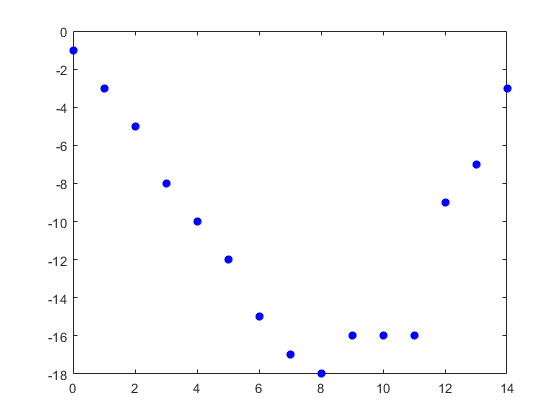

%convergeix a 1.5

plot(k,fix(log(2*er)),'*b','LineWidth',2)